# Tutorial: Parameter estimation

This tutorial shows a small parameter estimation exercise. Note that parameter estimation capacities are currently limited in the Computational Physiology Toolbox.

### Load experimental data and visualize the initial guess

Load an experimental dataset (Warfarin, see Tutorial "Importing experimental data")

data = ImportableData('data/Warfarin_Holford1986.csv','Delimiter',',');
data.maprow('Species','Covariate');
data.maprow('Warfarin oral dose','Oral dosing','Compound','Warfarin');
data.maprow('Warfarin plasma concentration','Record','Site','pla');
expid = import(data)

1 experimental dataset(s) imported successfully.


expid = 	Individual object:

           type: 'Experimental data'
           name: 'ID 1'
         dosing: '1 Oral event(s)'
     physiology: '1 parameters defined'
    observation: '8 records'

Use builtin('disp',OBJ)) to see the underlying structure of the Individual object OBJ

We consider an observable adapted to an empirical compartmental model

obs  = Observable('SimplePK','pla','total','Mass/Volume');

Define a virtual individual for simulation

simid = Individual('Virtual');
simid.name = 'Initial guess';
simid.dosing    = expid.dosing;
simid.drugdata  = DrugData('Warfarin','species','human');
simid.sampling  = Sampling([0 36]*u.h, obs);
simid.model     = empirical1CMT_PLASMA_macroConstants_linearCL;
simid.model.par = parameters(...
    'V',          15*u.L, ...          
    'CL',         0.3*u.L/u.h, ...     
    'lambda_po',  1.5/u.h, ...         
    'F',          1);

Initialize and simulate the model

initialize(simid)
simulate(simid)

Compare predicted to experimental plasma concentrations:

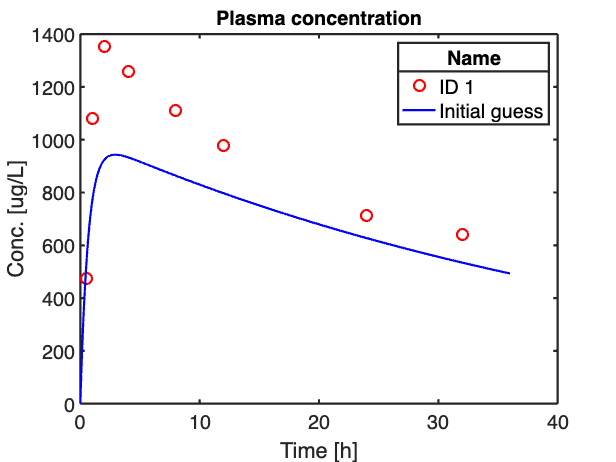

defaultPlots([expid simid],'plasmaConcentration','group_by','Name')

## Estimation using method `estimate()`

Define a virtual individual for specifying the estimation task:

estid = Individual('Virtual');

estid.model  = empirical1CMT_PLASMA_macroConstants_linearCL;


Convert Observable type `'ExpData'` to `'SimplePK'`:

obs  = Observable('SimplePK','pla','total','Mass/Volume');
expid.observation.Observable(:) = obs;

Associate the experimental data, specify the initial guess and fix the bioavailability parameter (only p.o. data available, hence we estimate effective CL and V parameters)

estid.estim.data = expid;
estid.estim.parinit = simid.model.setup.par;
estid.estim.options = estimset('fixed',{'F'});

Run the estimation task

estimate(estid)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    5.025445e-07     0.000e+00     1.000e+00     0.000e+00     3.832e+00  
    1          15    4.079336e-07     0.000e+00     7.000e-01     4.781e-04     5.193e+00  
    2          40    4.079092e-07     0.000e+00     1.628e-03     1.056e-04     2.916e+00  
    3          51    4.008249e-07     0.000e+00     2.401e-01     4.769e-04     2.302e+00  
    4          60    3.636739e-07     0.000e+00     4.900e-01     1.725e-03     7.961e+00  
    5          70    3.348287e-07     0.000e+00     3.430e-01     1.324e-03     1.152e+01  
    6          77    1.964726e-07     0.000e+00     1.000e+00     4.268e-04     1.283e+00  
    7          84    1.036446e-07     0.000e+00     1.000e+00     1.142e-03     2.282e-01  
    8          94    6.471381e-08     0.000e+00     3.430e-01     8.747e-04     7.

Plot the estimation result

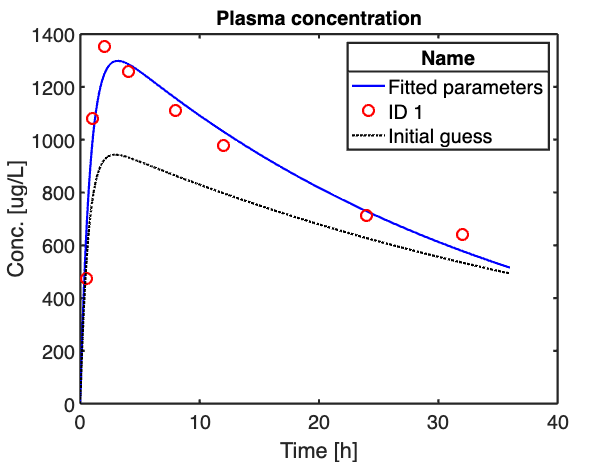

estid.model.par = estid.estim.parestim;
estid.sampling  = simid.sampling;
estid.dosing    = simid.dosing;
estid.name = 'Fitted parameters';

initialize(estid)
simulate(estid)

defaultPlots([expid estid simid],'plasmaConcentration')

### Goodness-of-fit plots

Goodness-of-fit plots can be created based on function `residuals()`

rtab = residuals(estid.model, expid)

rtab = 8×5 table
    Time               Observable                Prediction       Observation        Residuals   
    _____    ______________________________    ______________    ______________    ______________

    0.5 h    SimplePK|pla-total-Mass/Volume    642.1654 ug/L     472.4137 ug/L     -169.7517 ug/L
    1 h      SimplePK|pla-total-Mass/Volume    982.8721 ug/L     1079.3103 ug/L    96.4382 ug/L  
    2 h      SimplePK|pla-total-Mass/Volume    1246.7269 ug/L    1351.7241 ug/L    104.9972 ug/L 
    4 h      SimplePK|pla-total-Mass/Volume    1286.7023 ug/L    1258.6206 ug/L    -28.0817 ug/L 
    8 h      SimplePK|pla-total-Mass/Volume    1156.4177 ug/L    1110.3448 ug/L    -46.0729 ug/L 
    12 h     SimplePK|pla-total-Mass/Volume    1030.4169 ug/L    979.3103 ug/L     -51.1066 ug/L 
    24 h     SimplePK|pla-to

Residual plot

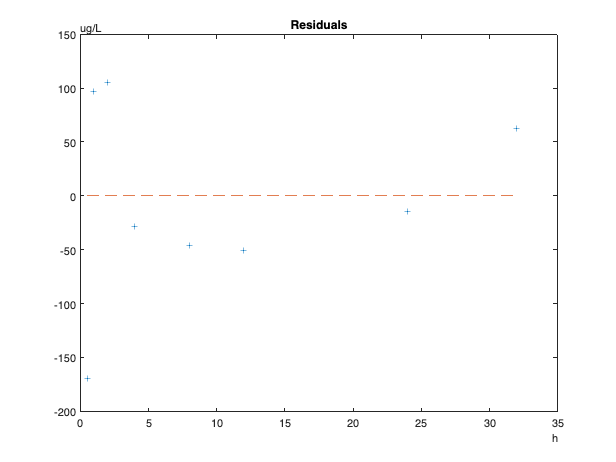

figure()
plot(rtab.Time,rtab.Residuals,'+',rtab.Time,0*rtab.Residuals,'--')
title('Residuals')

"Obs-vs-Pred" plot

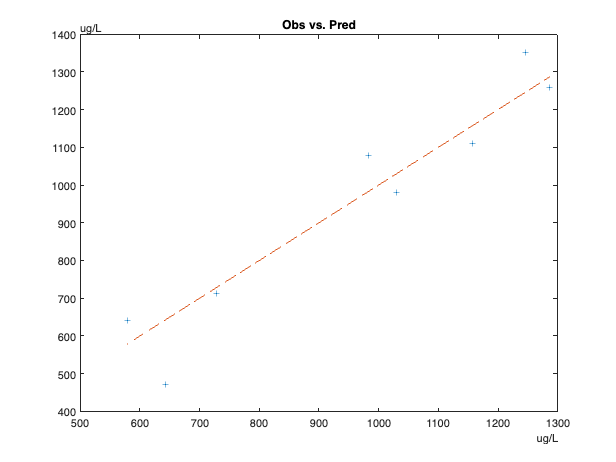

figure()
plot(rtab.Prediction,rtab.Observation,'+',rtab.Prediction,rtab.Prediction,'--')
title('Obs vs. Pred')